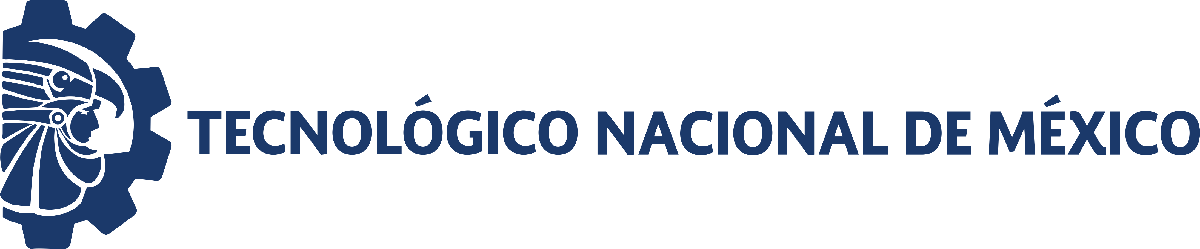                                 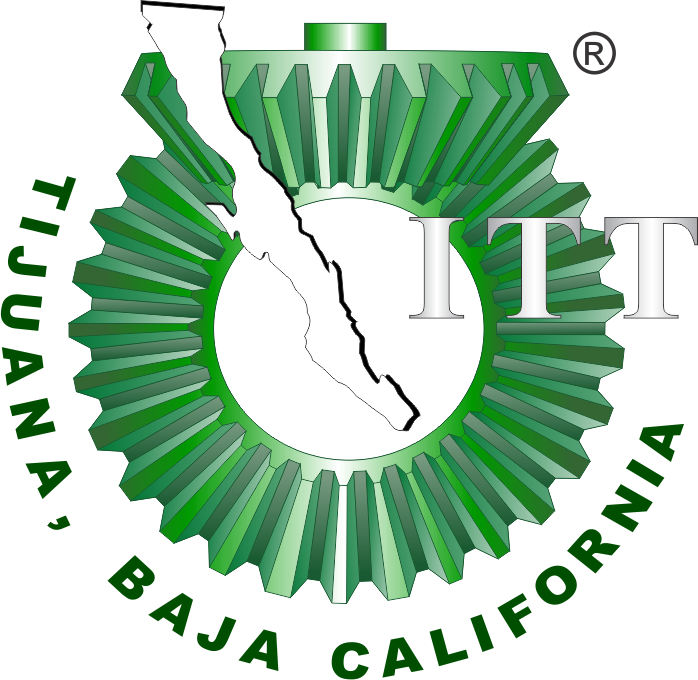

# Práctica 3: Sistema musculo-esquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

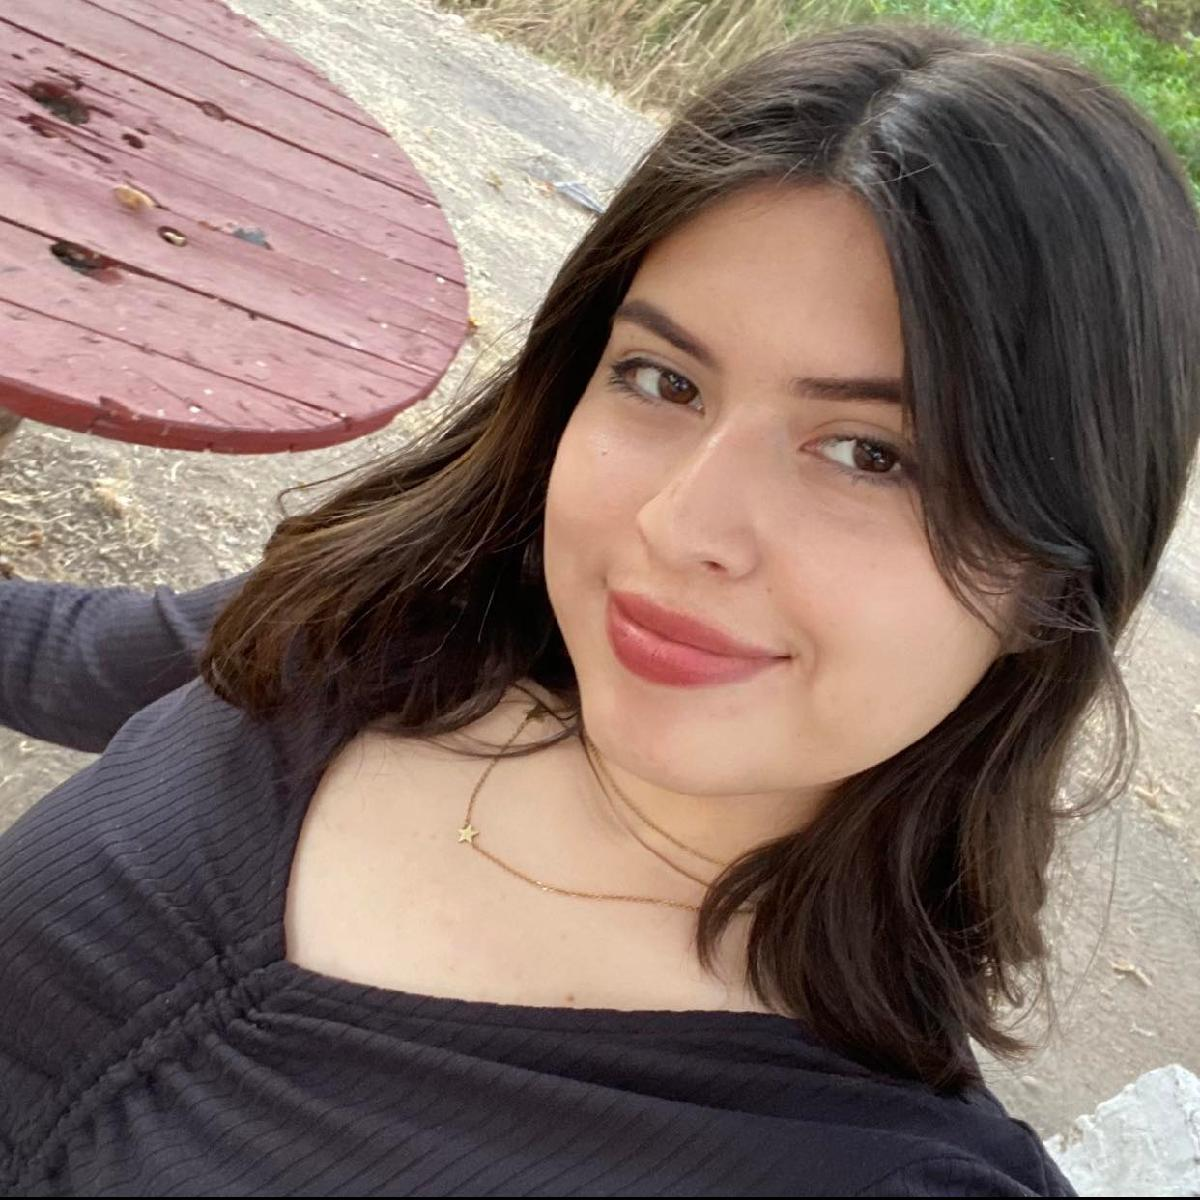

Nombre del alumno: **Lugo Valenzuela Liliana Fernanda**

Número de control: **21212165**

Correo institucional: **L21212165@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación


clc; clear; close all; warning('off','all')
tend = '10';
file = 'Practica3';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode45';
parameters.MaxStep = '1E-3';

x = sim(file,parameters);

Found algebraic loop containing: 
Practica3/PID Controller1/D Gain/Internal Parameters/Derivative Gain
Practica3/PID Controller1/Filter/Cont. Filter/SumD (algebraic variable)
Practica3/PID Controller1/N Gain/Internal Parameters/Filter Coefficient
Practica3/PID Controller1/Parallel P Gain/Internal Parameters/Proportional Gain
Practica3/PID Controller1/Sum/Sum_PID/Sum


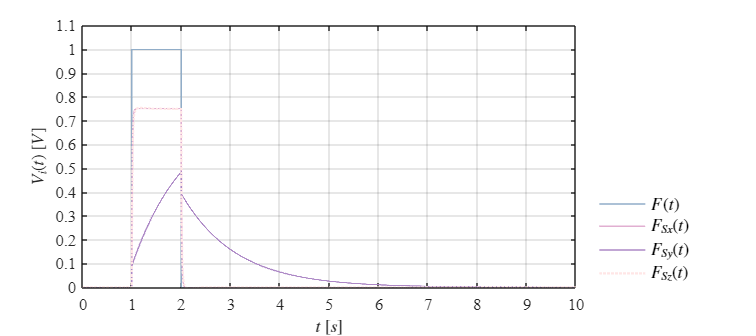


plotsignals(x.t,x.F,x.Fs1,x.Fs2,x.Fs3)


x2 = sim(file,parameters);

Found algebraic loop containing: 
Practica3/PID Controller1/D Gain/Internal Parameters/Derivative Gain
Practica3/PID Controller1/Filter/Cont. Filter/SumD (algebraic variable)
Practica3/PID Controller1/N Gain/Internal Parameters/Filter Coefficient
Practica3/PID Controller1/Parallel P Gain/Internal Parameters/Proportional Gain
Practica3/PID Controller1/Sum/Sum_PID/Sum


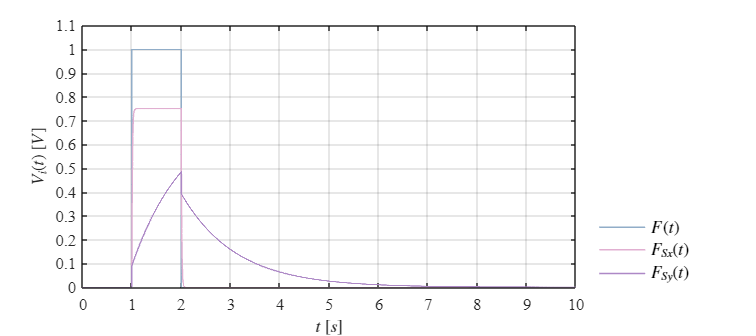

plotsignals2(x2.t,x2.F,x2.Fs1,x2.Fs2)

## Funcion: Respuesta a las señales

function plotsignals(t,F,Fs1,Fs2,Fs3)
set(figure(),'Color','w');
set(gcf,'units','centimeters','position',[1,1,18,8]);
set(gca,'FontName','Times New Roman','FontSize',11);
hold on; grid on; box on;
plot(t,F,'LineWidth',1,'Color',[0.568, 0.678, 0.784]); % 
plot(t,Fs1,'LineWidth',1,'Color',[0.882, 0.686, 0.820]); % 
plot(t,Fs2,'LineWidth',1,'Color',[0.678, 0.533, 0.776]); % 
plot(t,Fs3,':','LineWidth',1.5,'Color',[1.000, 0.902, 0.902]); 
L = legend('$F(t)$','$F_{Sx}(t)$','$F_{Sy}(t)$','$F_{Sz}(t)$');
set(L,'Interpreter','Latex','FontSize',11,'Location','southeastoutside','Box','Off');
xlabel('$t$ $[s]$', 'Interpreter','Latex','FontSize',11);
ylabel('$V_i(t)$ $[V]$', 'Interpreter','Latex','FontSize',11);
xlim([0,10]); xticks(0:1:10);
ylim([0,1.1]); yticks(0:0.1:1.1);
%exportgraphics(gcf,['Sistema Musculoesquelético','.pdf'],'ContentType','vector');
%exportgraphics(gcf,['Sistema Musculoesquelético','.png'],'Resolution',600);
print('Sistema Musculoesquelético','-dsvg','-r600');
print('Sistema Musculoesquelético','-depsc','-r600');
end



function plotsignals2(t,F,Fs1,Fs2)
set(figure(),'Color','w');
set(gcf,'units','centimeters','position',[1,1,18,8]);
set(gca,'FontName','Times New Roman','FontSize',11);
hold on; grid on; box on;
plot(t,F,'LineWidth',1,'Color',[0.568, 0.678, 0.784]); % 
plot(t,Fs1,'LineWidth',1,'Color',[0.882, 0.686, 0.820]); % 
plot(t,Fs2,'LineWidth',1,'Color',[0.678, 0.533, 0.776]); % 
%plot(t,Fs3,':','LineWidth',1.5,'Color',[1.000, 0.902, 0.902]); 
L = legend('$F(t)$','$F_{Sx}(t)$','$F_{Sy}(t)$');
set(L,'Interpreter','Latex','FontSize',11,'Location','southeastoutside','Box','Off');
xlabel('$t$ $[s]$', 'Interpreter','Latex','FontSize',11);
ylabel('$V_i(t)$ $[V]$', 'Interpreter','Latex','FontSize',11);
xlim([0,10]); xticks(0:1:10);
ylim([0,1.1]); yticks(0:0.1:1.1);
%exportgraphics(gcf,['Sistema Musculoesquelético','.pdf'],'ContentType','vector');
%exportgraphics(gcf,['Sistema Musculoesquelético','.png'],'Resolution',600);
print('Sistema Musculoesquelético1','-dsvg','-r600');
print('Sistema Musculoesquelético1','-depsc','-r600');
end





